# Kalman Filter Applied to a Quarter-Car Model

## Introduction

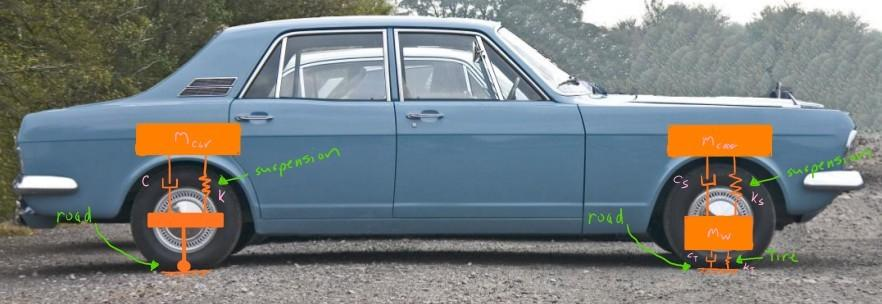

Let us consider the simplified "quarter car" model of the front suspension system, or of the rear suspension system of a car (as in the image). Such a quarter car model can be described by the following equations

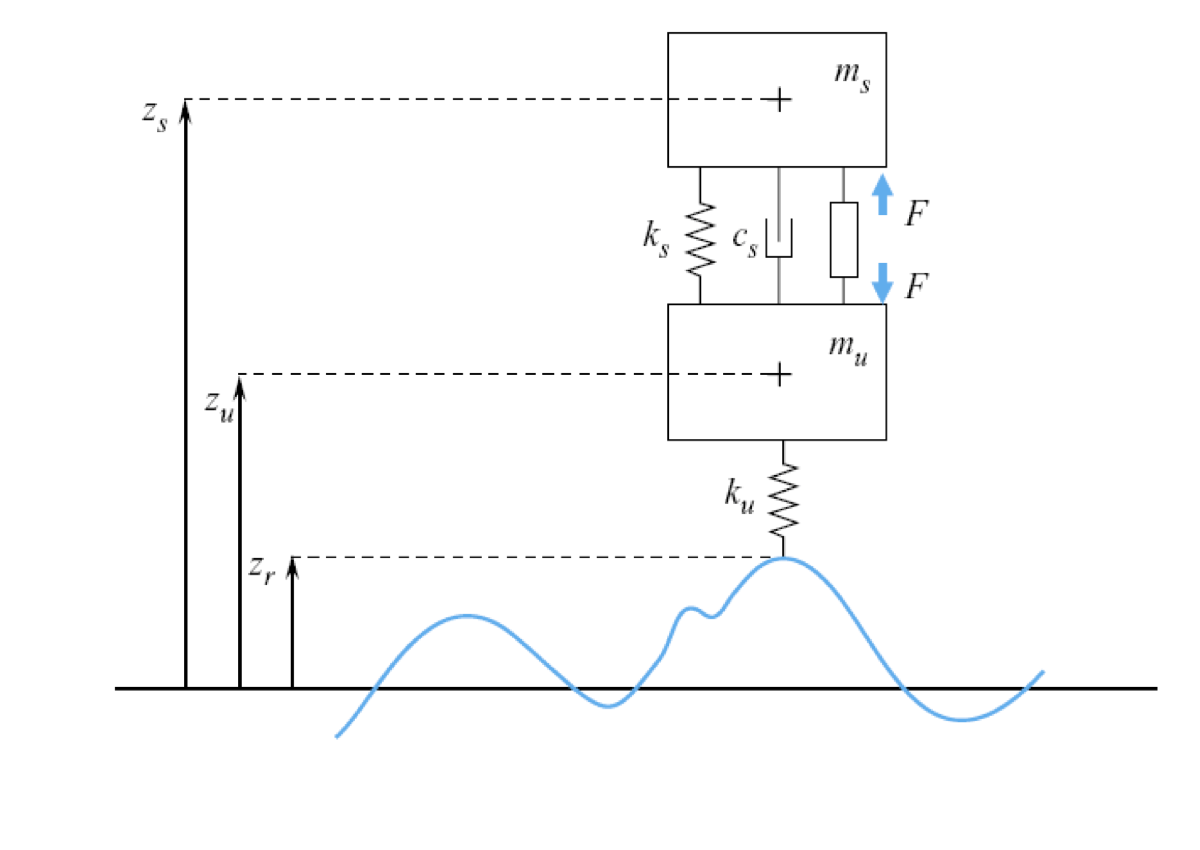


$$\[
 \left\{ 
\begin{array}{rcl}
  \left[\begin{array}{c} \dot{x}_1 \\ \dot{x}_2 \\ \dot{x}_3 \\ \dot{x}_4 \end{array} \right]&=& 
	 \left[ \begin{array}{cccc}
		0 & 0 & 1 & 0 \\[1 em]
		0 & 0 & 0 & 1 \\[1 em]
		\displaystyle \frac{k_s}{m_s} & \displaystyle\frac{k_s}{m_s} &\displaystyle -\frac{c_s}{m_s} & \displaystyle\frac{c_s}{m_s} \\[1 em]
		\displaystyle\frac{k_s}{m_u} &\displaystyle -\frac{k_s+k_u}{m_u} & \displaystyle\frac{c_s}{m_u} & \displaystyle -\frac{c_s}{m_u}
		\end{array} \right]  \cdot  \left[\begin{array}{c} x_1 \\ x_2 \\ x_3 \\ x_4 \end{array}\right] + 
		 \left[\begin{array}{cc} 0 & 0 \\[1 em] 0 & 0\\[1 em] 0 & \displaystyle\frac{1}{m_s} \\[1 em]\displaystyle\frac{k_s}{m_u} & \displaystyle-\frac{1}{m_u} \end{array} \right]
									\cdot \left[\begin{array}{c} u_1 \\ u_2 \end{array}\right] \\[2 ex]\\
		 \left[\begin{array}{c} y_1 \\ y_2  \end{array} \right] &=& 
			\left[\begin{array}{cccc}
				\displaystyle-\frac{k_s}{m_s} & \displaystyle\frac{k_s}{m_s} &\displaystyle -\frac{c_s}{m_s} &\displaystyle \frac{c_s}{m_s} \\[1 em]
				0 & k_u & 0 & 0
			\end{array} \right] \cdot \left[\begin{array}{c} x_1 \\ x_2 \\ x_3 \\ x_4 \end{array} \right] +
			\left[\begin{array}{cc}
				0 & \displaystyle\frac{1}{m_s} \\[1 em]
				-k_u & 0
				\end{array} \right] \cdot\left[\begin{array}{c} u_1 \\ u_2 \end{array}\right] 
\end{array}  \right.
\]
$$


Parameters:

- the sprung mass, i.e., a quarter of the vehicle mass $m_s$;

- the unsprung mass: the mass of one wheel $m_u$;

- the spring constant  $k_s$ of the passive suspension actuator; 

- the damping coefficient of the passive suspension damper $c_s$;

- the spring constant of the tyre $k_u$ 

Inputs:

- ground vertical position vs. the steady-state ground elevation [m];

- active actuator force [N].

Outputs:

- sprung mass vertical acceleration;

- contact force between the tyre and the ground.

State variables:

- vertical positions of sprung and unsprung masses vs. the corresponding steady-state values;

- vertical speeds of masses.


$$\left\{
\begin{array}{rcl}
	x_1(t) &=&  z_{s}(t)-\bar{z}_s \\
	x_2(t) &=&  z_{u}(t)-\bar{z}_u \\
	x_3(t) &=& \dot{x}_1(t)\\
	x_4(t) &=& \dot{x}_2(t)\\[1.5 ex]
	u_1(t) &=& z_{r}(t)-\bar{z}_{r}\\
	u_2(t) &=& F(t) \\[1.5 ex]
	y_1(t) &=& \ddot{x}_1(t) \\
	y_2(t) &=& k_u \left( x_2(t) - u_1(t) \right)
\end{array} \right.$$


### Hypotheses of the quarter-car model:

- The vehicle is assumed to be an assembly of four decoupled parts;

- Each part consists of the sprung mass [i.e., a quarter of the vehicle mass, supported by a suspension actuator, placed between the vehicle and the tyre] and the unsprung mass [i.e., the wheel+tyre subassembly];

- The model allows only for vertical motion. The vehicle is moving forward at an almost constant speed. 

### Reference

- Antsaklis  P. J.  & Michel  A. N. (2006). *Linear systems*. Birkhäuser.

## The Model

### Initialisation 

% cleaning the Matlab workspace

close all
clear
clc

% and assigning the parameters
% 
mS = 375;   % [kg] sprung mass
mU = 30;    % [kg] unsprung mass
kS = 1500;  % [N/m] spring stiffness of the passive suspension system
kU = 6500;  % [N/m] spring stiffness of the tyre
cS = 1125;  % [N s/m] damping constant 

### The continuous-time LTI system

% the matrices of the LTI system equations
matA = [   0           0      1     0   ;...
             0           0      0     1   ;...
          -kS/mS       kS/mS -cS/mS  cS/mS ;...
           kS/mU -(kS+kU)/mU  cS/mU -cS/mU];
       
matB = [   0      0  ;...
             0      0  ;...
             0     1/mS;...
           kU/mU  -1/mU];  
       
matC = [ -kS/mS    kS/mS   -cS/mS    cS/mS;...
              0       kU        0        0];
          
matD = [0 1/mS; -kU 0];

% let's create a continuous-time LTI system
LTI_q_carC = ss(matA, matB, matC, matD);



### Sampling the LTI system

Ts = 1/1000; % sampling period [s]

sysD1 = c2d(LTI_q_carC,Ts); % the sampling-time description of the quarte-car model
Ad1=sysD1.A; Bd1=sysD1.B;
Cd1=sysD1.C; Dd1=sysD1.D;

## The Experiment

Let us perform the following experiment

- apply a step to the quarter-car system, using both the inputs $u_1(k)$ [ground vertical position vs. the steady-state] and $u_2(k)$ [active actuator force]; in details, an increment of $0.1 \mathrm{m}$for $u_1(k)$ and a step from $0\;\mathrm{N}$ to $10000\;\mathrm{N}$ for the input $u_2(k)$;

- collect the measurements of the outputs $y_1(k)$ [sprung mass vertical acceleration] and $y_2(k)$ [contact force between the tyre and the ground];

- for comparison with the Kalman filter estimate, collect also the state variable movenet in the theoretical "measurement noise free" situation.

### The Noise-free Baseline

% --- step inputs configuration ---
% let's configure the step inputs
%
% 1st input <-- ground vertical position vs. the steady-state ground
%               elevation [m] <--> an increment of 0.1 m
% 2nd input <-- active actuator force [N] <--> from 0 N to 10000 N
%
U1ampl = 0.1; % step magnitude for the 1st input
U2ampl = 1e5; % step magnitude for the 2nd input
opt = stepDataOptions('StepAmplitude',[U1ampl, U2ampl]);
% ----------------------------------


% --- final time instant fo the step outputs evaluation
Tfinal = 5.5; % s

% --- step outputs evaluation ---
[Yd1, Td1, Xd_no_noise] = step(sysD1, Tfinal, opt);

% the inputs are acting at the same time, but "step" command is evaluating
% the state and outputs using the superposition principle:
%
% Yd1(:,:,1) --> outputs corresponding to the 1st input only acting on the
%                system; in details 
%                Yd1(:,1,1) and Yd1(:,2,1) are respectively the 1st and 
%                the 2nd output sequence
%
% Yd1(:,:,2) --> outputs corresponding to the 2nd input only acting on the
%                system; in details 
%                Yd1(:,1,2) and Yd1(:,2,2) are respectively the 1st and 
%                the 2nd output sequence
%

yOUT1_1_no_noise = Yd1(:,1,1); % 1st output due to the 1st input only
yOUT2_1_no_noise = Yd1(:,2,1); % 2nd output due to the 1st input only
Xno_noise_1 = Xd_no_noise(:,:,1);% state evolution when only 
                         % the 1st input is acting on the system

yOUT1_2_no_noise = Yd1(:,1,2); % 1st output due to the 2nd input only
yOUT2_2_no_noise = Yd1(:,2,2); % 2nd output due to the 2nd input only

Y1 = (yOUT1_1_no_noise+yOUT1_2_no_noise)';
Y2 = (yOUT2_1_no_noise+yOUT2_2_no_noise)';
Y_no_noise = [Y1; Y2];

Xno_noise_2 = Xd_no_noise(:,:,2);% state evolution when only 
                         % the 2nd input is acting on the system
                         
Xno_noise = Xno_noise_1 + Xno_noise_2;
Xno_noise = Xno_noise'; % tthe state variables in the noise-free scenario


### Noise Acting on Measurements and Process

Now let us assume that the measurements are affected by noise, whereas the so called "process noise" is very low (i.e. no relevant disturbances or uncertainties are acting on the state dynamics):

% [m/s^2] the standard deviation of the displacement measurement noise
meas_acc_noise_STD = 16; 

% [N] the standard deviation of the force measurement noise
meas_force_noise_STD = 2500;

% process noise STD
proc_noise_STD = 0.000001; 

 

#### Simulating the Noisy System

rng('shuffle'); % initialization of the random nuumber generators
Xnoisy = zeros(size(Xno_noise));
Ynoisy = zeros(size(Y_no_noise));

v1 = proc_noise_STD*randn(size(Xnoisy));
v2 = [meas_acc_noise_STD*randn(size(Td1'));...
      meas_force_noise_STD*randn(size(Td1'))];

for k=1:numel(Td1)-1
    Xnoisy(:,k+1) = Ad1*Xnoisy(:,k)+ Bd1*[U1ampl;U2ampl]+v1(:,k);
    % qua aggiungo  il rumore sia ad X che ad Y perche` le formulazioni
    % fisiche che sto usando non sono certe al 100% (ci sono anche altri
    % fenomeni che non tengo in considerazione)
    Ynoisy(:,k) = Cd1*Xnoisy(:,k)+ Dd1*[U1ampl;U2ampl]+v2(:,k); 
end % for k
Ynoisy(:,numel(Td1)) = Cd1*Xnoisy(:,numel(Td1))+ Dd1*[U1ampl;U2ampl]+v2(:,numel(Td1));

TimeSamples = Td1;

#### Plotting the Outputs

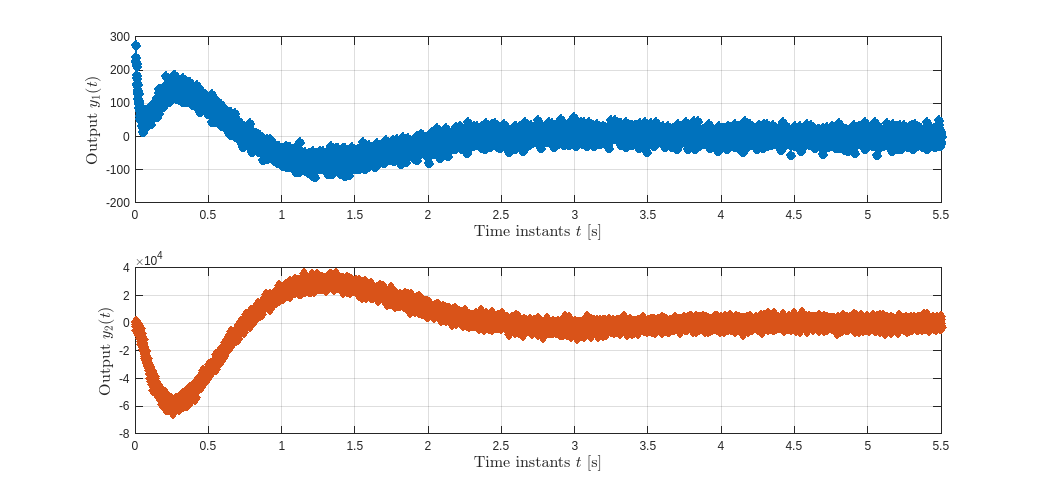

% ---- possible colors ----
FrenchBlue   = [0 0.4470 0.7410];      % French Blue
FlameRed     = [0.8500 0.3250 0.0980]; % Flame Red
Xanthous     = [0.9290 0.6940 0.1250]; % Xanthous
VividViolet  = [0.4940 0.1840 0.5560]; % Vivid Violet
AppleGreen   = [0.4660 0.6740 0.1880]; % Apple Green
BlizzardBlue = [0.3010 0.7450 0.9330]; % Blizzard Blue
VividBurgundy = [0.6350 0.0780 0.1840]; % Vivid Burgundy
% ---- possible colors ----

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);

hp1  = subplot(2,1,1);
plot(TimeSamples, Ynoisy(1,:), "Color", FrenchBlue, "LineStyle","-", "LineWidth", 1.5, ...
    "Marker","o", "MarkerEdgeColor", FrenchBlue, "MarkerFaceColor", FrenchBlue, ...
    "MarkerSize", 6);
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
ylabel(' Output $y_1(t)$', 'Interpreter','latex', 'FontSize', 12);

hp2 = subplot(2,1,2);
plot(TimeSamples, Ynoisy(2,:),'Color', FlameRed, 'LineStyle','-', 'LineWidth', 1.5, ...
    'Marker','diamond', 'MarkerEdgeColor', FlameRed, 'MarkerFaceColor', FlameRed, ...
    'MarkerSize',6);
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
ylabel(' Output $y_2(t)$', 'Interpreter','latex', 'FontSize', 12);

linkaxes([hp1, hp2], 'x');

## The Kalman Filter as State Predictor

We want to predict the state variables one step ahead (in the future) $\hat{x}\left(t+1 \vert t\right)$ using the measurements of inputs and outputs till the actual time instant $u(t),\; y(t)$ by means of the Kalman Filter

Given the system dynamics described by


$$\left\{ \begin{array}{rcl}
	x(t+1) &=& F x(t) + G u(t)+ v_1(t) \\
	y(t) &=& H x(t) + D u(t) +v_2(t) \qquad x, \, v_1 \in \mathbb{R}^n, \, y, \, v_2 \in \mathbb{R}^p
	\end{array} \right.$$


the Kalman filter acting as one-step ahead predictor is


$$\left\{
\begin{array}{rcl}
\hat x(t+1 \, \vert \, t) &=&
			F \, \hat x (t\, \vert \,t-1)+G\,u(t)
			+ K(t) \cdot \big(y(t)-H\,\hat x (t\, \vert \,t-1)-D\,u(t)\big)  \\
K(t) &=& F \cdot P(t) \cdot H^{\top}
			\left [
			H \cdot P(t) \cdot H^{\top} + V_2
			\right ]^{-1} \\ 
P(t+1) &=& F \, \left \{
			P(t) - P(t) H^{\top} \,
			\left [
			V_2 + H P(t) H^{\top}
			\right ]^{-1} \, H P(t)
			\right \} \, F^{\top} + V_1
\end{array}
\right.$$


% ------------------------------
% system model equations
%
% x(k+1) = F x(k) + G u(k) + v1(k)
%   y(k) = H x(k) + D u(k) + v2(k) 
%
% v1(k), v2(k) i.i.d. gaussian white noises
%
% state vector x(k)
% 
% x(k) = [x1(k) x2(k) x3(k) x4(k)]'
%

F = Ad1; G = Bd1;
H = Cd1; D = Dd1;
Nx = size(F,1);
uU1 = U1ampl * ones(size(TimeSamples))';
uU2 = U2ampl * ones(size(TimeSamples))';
uU = [uU1; uU2];


Setting the process and measurements noise variance matrices

V1 = diag([1000*proc_noise_STD.^2; ...
            1000*proc_noise_STD.^2; ...
            proc_noise_STD.^2; ...
            proc_noise_STD.^2]); 
V2 = diag([meas_acc_noise_STD.^2 ; meas_force_noise_STD.^2]);

**Suggestion**: modify the variance matrices and explore what happens to the state estimation!

The initial state and the corresponding uncertainty matrix

x1 = zeros(Nx,1);
P1 = diag([1e6;1e6;1e3;1e3]);

**Suggestion**: modify the variance matrix $P_1$ and/or thee initial state $x_1$ and explore what happens to the state estimation!

### The Kalman Predictor


$$\left\{
\begin{array}{rcl}
\hat x(t+1 \, \vert \, t) &=&
			F \, \hat x (t\, \vert \,t-1)+G\,u(t)
			+ K(t) \cdot \big(y(t)-H\,\hat x (t\, \vert \,t-1)-D\,u(t)\big)  \\
K(t) &=& F \cdot P(t) \cdot H^{\top}
			\left [
			H \cdot P(t) \cdot H^{\top} + V_2
			\right ]^{-1} \\ 
P(t+1) &=& F \, \left \{
			P(t) - P(t) H^{\top} \,
			\left [
			V_2 + H P(t) H^{\top}
			\right ]^{-1} \, H P(t)
			\right \} \, F^{\top} + V_1
\end{array}
\right.$$


N = numel(TimeSamples);

xhat = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
xhat(:,1) = x1; % 1st state a priori estimation

y = Ynoisy; % the measurements
e = zeros(size(y)); % innovation 

P = zeros(Nx,Nx,N);
P(:,:,1) = P1; % 1st P matrix

% ------ evaluating the state prediction ---------
for k = 1:(N-1)
    
    e(:,k) = y(:,k) - (H*xhat(:,k)+D*uU(:,k));
    cP = P(:,:,k);
    K = (F*cP*H')/(H*cP*H'+V2);
    xhat(:,k+1) = F*xhat(:,k) +G*uU(:,k)+ K*e(:,k);
    Pnew = V1+F*(cP-(cP*H'/(V2+H*cP*H'))*H*cP)*F';
    if (k<N)
        P(:,:,k+1) = Pnew;
    end
    
end % for k 



### Comparison of the State Predictions with the Noise-free Scenario State

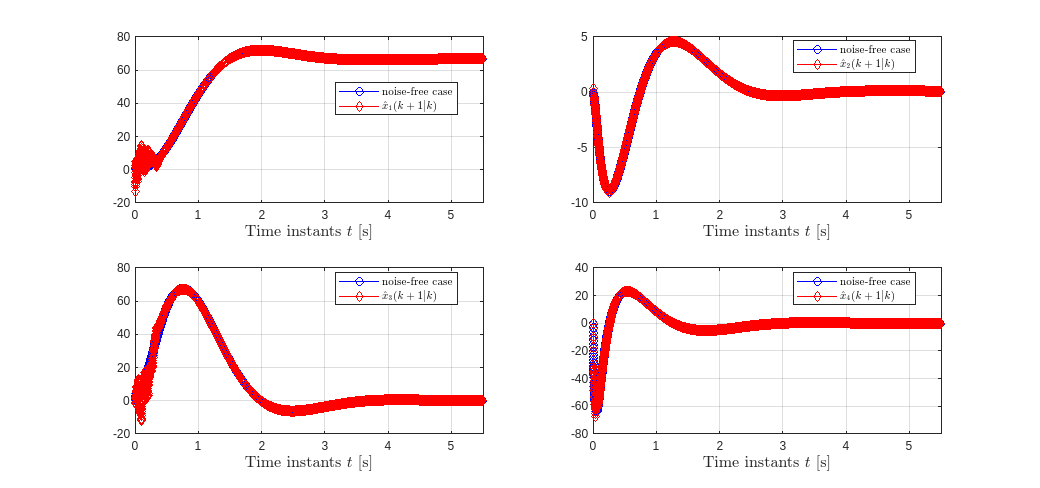

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
hp1 =subplot(2,2,1);
plot(TimeSamples, Xno_noise(1,:),'bo-'); hold on
plot(TimeSamples,  xhat(1,:),'rd-')
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{1}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp2= subplot(2,2,2);
plot(TimeSamples, Xno_noise(2,:),'bo-'); hold on
plot(TimeSamples,  xhat(2,:),'rd-');
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{2}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp3 = subplot(2,2,3);
plot(TimeSamples, Xno_noise(3,:),'bo-'); hold on
plot(TimeSamples,  xhat(3,:),'rd-');
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{3}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp4 = subplot(2,2,4);
plot(TimeSamples, Xno_noise(4,:),'bo-'); hold on
plot(TimeSamples,  xhat(4,:),'rd-');
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{4}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

linkaxes([hp1, hp2, hp3, hp4], 'x')

To better pointing in evidence the prediction error, let us plot the difference between the noise-free state and the predicted one

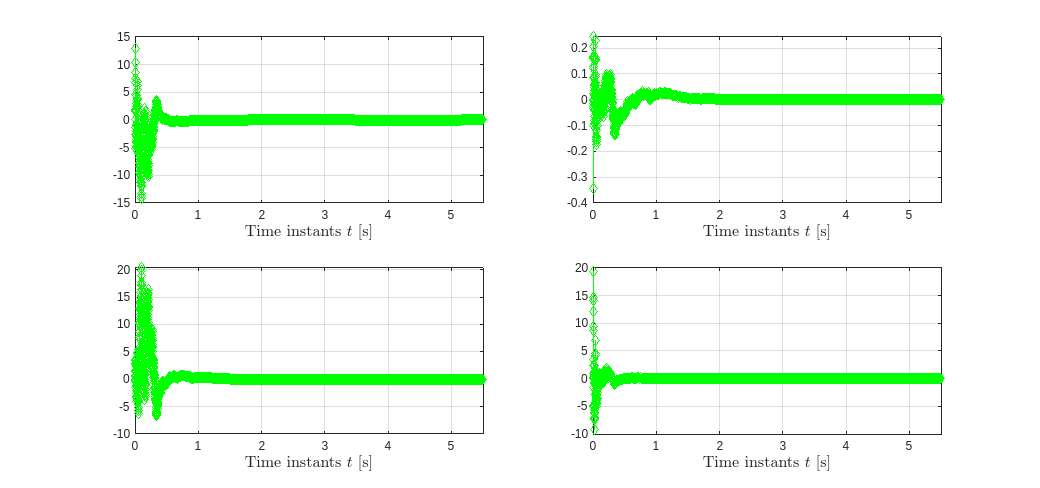

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
p1=subplot(2,2,1);
plot(TimeSamples, Xno_noise(1,:)-xhat(1,:),'gd-'); 
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);

p2=subplot(2,2,2);
plot(TimeSamples, Xno_noise(2,:)-xhat(2,:),'gd-'); 
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);

p3=subplot(2,2,3);
plot(TimeSamples, Xno_noise(3,:)-xhat(3,:),'gd-');
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);

p4=subplot(2,2,4);
plot(TimeSamples, Xno_noise(4,:)-xhat(4,:),'gd-');
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
linkaxes([p1, p2, p3, p4], 'x')

## Proposal: the Kalman Filter

Implement the $0$-steps ahead predictor $\hat{x}(t | t)$:


$$\left\{ \begin{array}{rcl}
\hat{x}\left( t \vert t \right) &=& \hat{x}\left(t \vert t-1 \right) + K_0(t) \cdot e(t) \\
              K_0(t) &=& P(t) \cdot H^{T} \left[H \cdot P(t)\cdot H^{T}+V_2  \right]^{-1}\\
P(t+1) &=& F \, \left \{
			P(t) - P(t) H^{\top} \,
			\left [
			V_2 + H P(t) H^{\top}
			\right ]^{-1} \, H P(t)
			\right \} \, F^{\top} + V_1
\end{array}
\right.$$


and compare the state estimate with the noise-free state.

N = numel(TimeSamples);

xhat_f = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
xhat_f(:,1) = x1; % 1st state a priori estimation
x_hat = zeros(Nx,N); % output of the Kalman 1-step ahead predictor
x_hat(:,1) = x1; % 1st state a priori estimation

y = Ynoisy; % the measurements
e = zeros(size(y)); % innovation 

P = zeros(Nx,Nx,N);
P(:,:,1) = P1; % 1st P matrix

% ------ evaluating the state prediction ---------
for k = 1:(N-1)
    
    e(:,k) = y(:,k) - (H*xhat_f(:,k)+D*uU(:,k));
    cP = P(:,:,k);
    K = (cP*H')/(H*cP*H'+V2);
    xhat_f(:,k+1) = F*xhat_f(:,k) + K*e(:,k); % predittore ad un passo avanti
    x_hat = xhat_f(:,k) + K*e(:,k); 
    % come equazione del sistema dinamico, uso il predittore ad un passo
    % avanti per determinare x(t|t)
    Pnew = V1+F*(cP-(cP*H'/(V2+H*cP*H'))*H*cP)*F';
    if (k<N)
        P(:,:,k+1) = Pnew;
    end
    
end % for k 

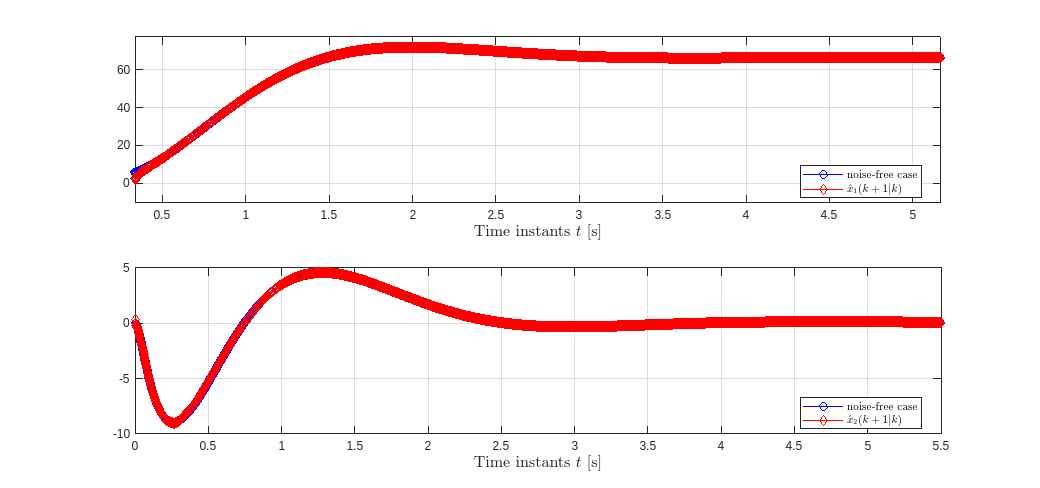

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
hp1 =subplot(2,1,1);
plot(TimeSamples, Xno_noise(1,:),'bo-'); hold on
plot(TimeSamples,  xhat(1,:),'rd-')
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{1}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');

hp2= subplot(2,1,2);
plot(TimeSamples, Xno_noise(2,:),'bo-'); hold on
plot(TimeSamples,  xhat(2,:),'rd-');
grid on; zoom on;xlim([min(TimeSamples), max(TimeSamples)]);
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
legend('noise-free case', '$\hat{x}_{2}(k+1 | k)$', 'Interpreter', 'latex',...
         'Location', 'best');